#### 2.3  Tutorial lsim with Differential Equations

The function l***sim ***can be used to simulate the output of continous-time, causal LTI systems described by linear constant-coefficient differential equations of the form

                $\sum^N _{k=0} a_k \frac{d^k y(t)}{dt^k}=\sum ^M _{m=0} b_m \frac{d^mx(t)}{dt^m}$                                                     (2.11)

To use ***lsim***, the cofficients  $$a_k$$ and $$b_m$$ must be stored in MATLAB vectors ***a*** and ***b***, respectively, in descending order of the indices ***k*** and ***m***.   Rewriting Eq. (2.11) in terms of the vectors  ***a*** and ***b *** gives

                $\sum ^N _{k=0 a} a(N+1-k) \frac{d^k y(t)}{dt^k}=\sum ^M _{m=0} b(M+1-m) \frac{d^m x(t)}{dt^m}$                 (2.12)          

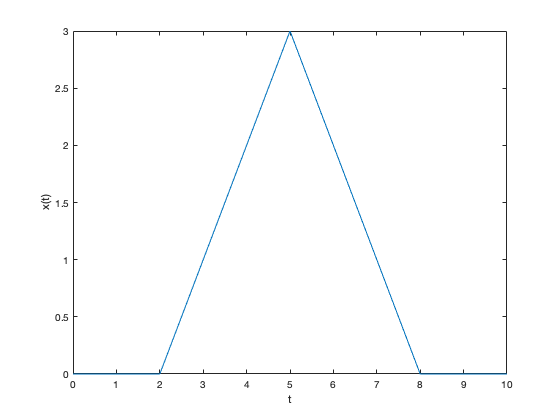

% sample code on page 26-27
clf;
% plot x(t)
t=[0 1 2 5 8 9 10];
x = [0 0 0 3 0 0 0];
figure
plot(t,x);
xlabel('t');   ylabel('x(t)');

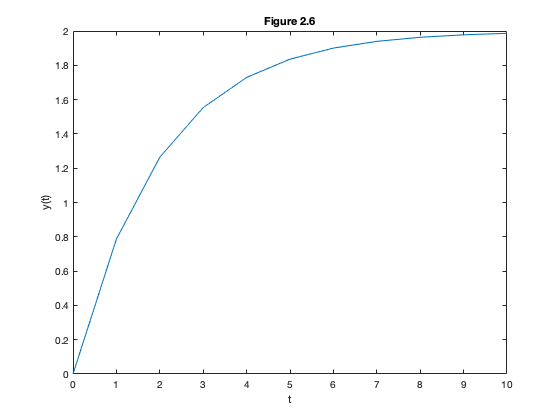


% plot y(t) 
t=[0:10];
x=ones(1,length(t));
b=1;
a=[1 0.5];
s=lsim(b,a,x,t);
figure;
plot(t,s);
%plot(t,s,'--');
title('Figure 2.6')
xlabel('t');   ylabel('y(t)');

The plot above shows the solid line reprsents the actual step response

                    $s(t)=2(1-e^{-t/2})u(t)$                (2.14)

**2.3 (a)  **

On your own, use lsim to compute the response of the causal LTI system descripted by

                    $\frac{dy(t)}{dt}=-2y+x(t)$                     (2.15)

to the imput $$x(t)=u(t-2)$$.  Your response should look like the plot in Figure 2.7, which is computed using t=[0:0.5:10].

**Analysis:   **The plot from the MATLAB program blow does agree with the plot in Figure 2.7.  It shows a shift to right by two units.

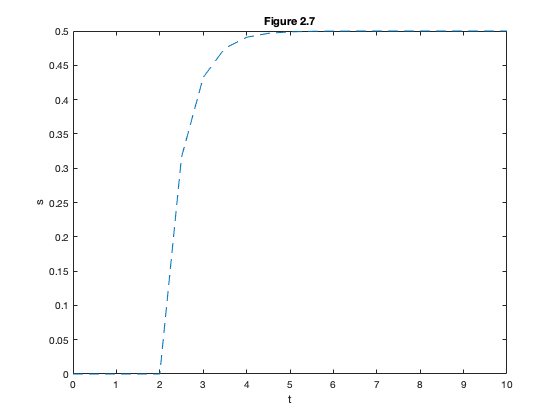

% L2_3a.m
clf;
t=[0:0.5:10];
x=ones(1,length(t));
b=1;
a=[1 2];
s=lsim(b,a,x,t);
st=[0; 0; 0; 0; s(1:17)];
figure;
plot(t,st,'--');
title('Figure 2.7')
xlabel('t');   ylabel('s');

**2.3 (b)**

Use the step and impulse to compute the*** step*** and ***impulse*** reponses of the causal LTI system characterized by Eq. (2.13). Compare the ***step ***resonse comuted by step with that shown in Figure 2.6.  Compare the signal returned by*** impulse*** with the exact impulse response, given by the derivative of s(t) in EQ. (2.14).

**Analysis:  **

- The plot of step resonse blow does agree with Figure 2.6.

- The plot of impulse resonse is shown below also.

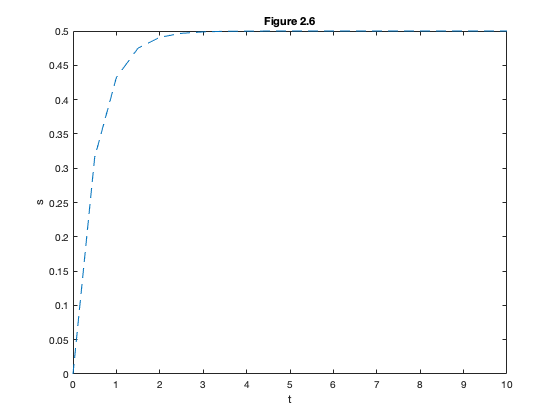

% L2_3b.m
% using the sample code on page 28-29.

clf;
t=[0:0.5:10];
x=ones(1,length(t));
b=1;
a=[1 2];
s=step(b,a,t);
figure;
plot(t,s,'--');
title('Figure 2.6')
xlabel('t');   ylabel('s');

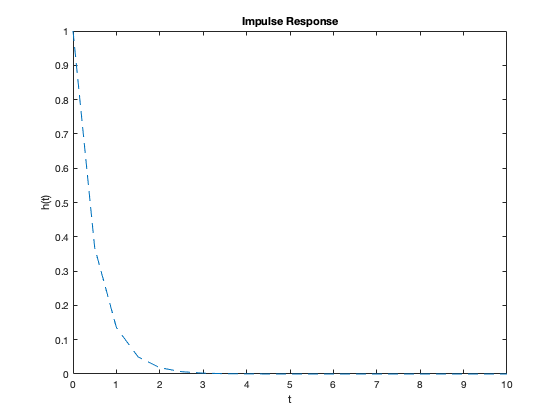

h=impulse(b,a,t);
figure;
plot(t,h,'--');
title('Impulse Response')
xlabel('t');   ylabel('h(t)');

#### 2.4  Properties of Discrete-Time Systems 

I this exercise, you will verify the commutative, associative and distriutive properties of convolution for a specific set signals.  In addition, you will examine the implications of these properties for serier and parallel connections of LTI systems.  This problems in this exercise will assume that you are confortable and familliar the conv function describled in Tutorial 2.1.

(a) Make appropriately labeled plots of all the signals using stem (see x1, h1 and h2 signals on page 30).

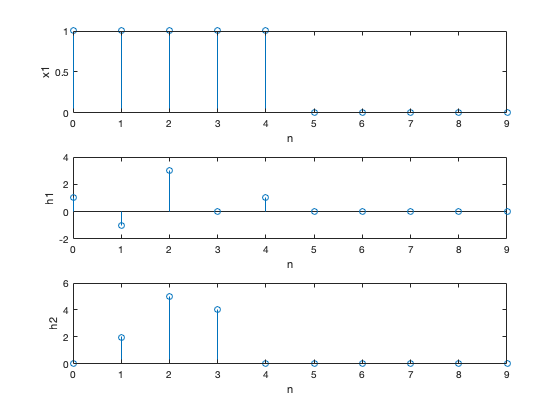

% L2_4a.m

n=[0:9];
x1=n*0;
h1=n*0;
h2=n*0;
for i=n
    
    if 0<=i & i<5
        x1(i+1)=1;
    end
end
h1(1)=1;
h1(2)=-1;
h1(3)=3;
h1(5)=1;
h2(2)=2;
h2(3)=5;
h2(4)=4;
h2(5)-1;
figure(1);
subplot(3,1,1);stem(n,x1); xlabel('n');ylabel('x1');
subplot(3,1,2);stem(n,h1); xlabel('n');ylabel('h1');
subplot(3,1,3);stem(n,h2); xlabel('n');ylabel('h2');

**2.4 (b**) Verify the commutative property of convoluaton operator.   

If $$y_1[n]=x[n]*h[n]$$  and $$y_2[n]=h[n]*x[n]$$,  then  $$$y_1[n] = y_2[n] $

**Analysis:   **The MATLAB code and plots does verify that $$$y_1[n] = y_2[n] $

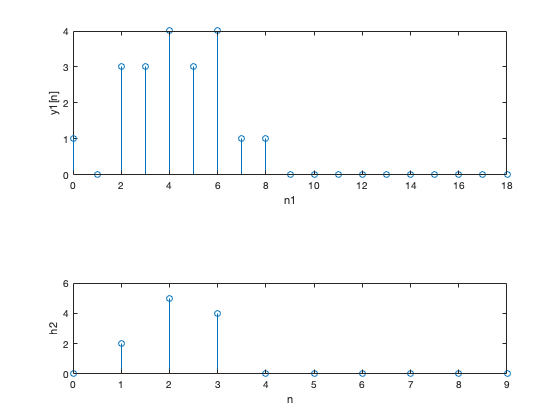

% L2_4b.m

n=[0:9];
x1=n*0;
h1=n*0;
for i=n
    
    if 0<=i & i<5
        x1(i+1)=1;
    end
end
h1(1)=1;
h1(2)=-1;
h1(3)=3;
h1(5)=1;
y1=conv(x1,h1);
n1=[0:length(y1)-1];
y2=conv(h1,x1);
n2=[0:length(y2)-1];

figure(1);
subplot(2,1,1);stem(n1,y1); xlabel('n1');ylabel('y1[n]');

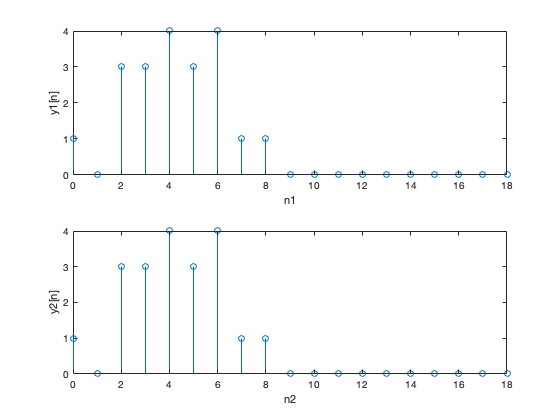

subplot(2,1,2);stem(n2,y2); xlabel('n2');ylabel('y2[n]');

**2.4 (c)  **Convolution is also distributive.  This means that

            
$$x[n]*(h_1[n]+h_2[n])=x[n]*h_1[n]+x[n]*h_2[n]$$


Do these two methods of computing the output give the same result?

**Analysis:  **The MATLAB code and plots below shows that  these two methods of computing the output do give the same result.  Therefore it verifies that convolution is distributive.

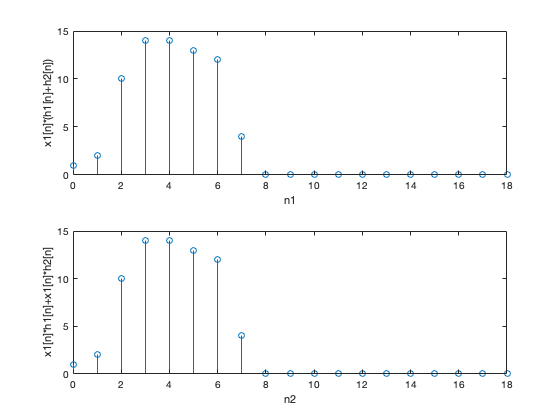

% L2_4c.m
% verify distributive property

n=[0:9];
x1=n*0;
h1=n*0;
h2=n*0;
for i=n
    
    if 0<=i & i<5
        x1(i+1)=1;
    end
end
h1(1)=1;
h1(2)=-1;
h1(3)=3;
h1(5)=1;
h2(2)=2;
h2(3)=5;
h2(4)=4;
h2(5)=-1;
h3=h1+h2;
y1=conv(x1,h3);
n1=[0:length(y1)-1];
y2=conv(x1,h1)+ conv(x1,h2);
n2=[0:length(y2)-1];
figure(1);
subplot(2,1,1);stem(n1,y1); xlabel('n1');ylabel('x1[n]*(h1[n]+h2[n])');
subplot(2,1,2);stem(n2,y2); xlabel('n2');ylabel('x1[n]*h1[n]+x1[n]*h2[n]');

**2.4 (d) ** Convolution also possesses that associative property, i.e.,

                
$$(x[n]*h_1[n])*h_2[n]=x[n]*(h_1[n]*h_2[n])$$


Use the following steps to verify the associative property using x1, h1, and h2:

- Let ***w[n]*** be the output of the LTI system with impulse response $$h_1[n]$$ shown in the Figure 2.9. Computer $$w[n]$$ by convolving $$x_1 [n]$$ and  $$h_1[n]$$.

- Compute the output $$y_{d1}[n]$$ of the whole system by convolving $$w[n]$$ with $$h_2 [n]$$.

- Find the impulse response $$h_{series}[n]=h_1[n]*h_2[n]$$

- Convolve $$x_1 [n]$$ with $$h_{series}[n]$$ to get the output $$y_{d2}[n]$$

Compare $$y_{d1}[n]$$ and $$y_{d2}[n]$$.  Did you get the same results when you process $$x_1[n]$$ with the indiviudal impulse responses as when you process it with $$h_{series}[n]$$. ?

**Analysis:  **The plots bow do show $$y_{d1}[n]$$ and $$y_{d2}[n]$$ are same. Therefore, it verifies the associative property is true for convolution operation in LTI systems.

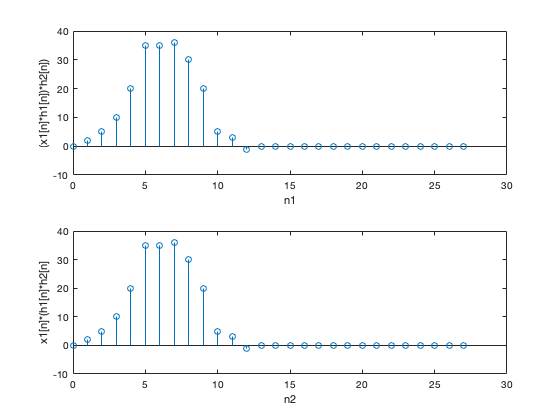

% L2_4d.m
% verify associative property
n=[0:9];
x1=n*0;
h1=n*0;
h2=n*0;
for i=n
    
    if 0<=i & i<5
        x1(i+1)=1;
    end
end
h1(1)=1;
h1(2)=-1;
h1(3)=3;
h1(5)=1;
h2(2)=2;
h2(3)=5;
h2(4)=4;
h2(5)=-1;
temp_y1=conv(x1,h1);
y1=conv(temp_y1,h2);
n1=[0:length(y1)-1];
temp_y2=conv(h1,h2);
y2=conv(x1,temp_y2);
n2=[0:length(y2)-1];
figure(1);
subplot(2,1,1);stem(n1,y1); xlabel('n1');ylabel('(x1[n]*h1[n])*h2[n])');
subplot(2,1,2);stem(n2,y2); xlabel('n2');ylabel('x1[n]*(h1[n]*h2[n]');

#### 2.5 Linearity and Time-invariance

The problems in this exercise assume that you are familiar with the functions conv and filter.  These functions are explained in Tutorial 2.1 and Tutorial 2.2.

Consider the systems:

    System 1:                $w[n]=x[n]-x[n-1]-x[n-2]$

    System 2:                $y[n]=cos(x[n])$

    System 3:                $z[n]=nx[n]$           

where x[n] is the input to each system, and w[n], y[n] and z[n] ar the corresponding outputs.

(a**) **Consider the three inputs signals $$x_1[n]=\delta[n]$$, $$x_2[n]=\delta[n-1]$$, and $$x_3[n]=(\delta[n]+2\delta[n-1])$$. For sysem1, store in w1, w2, and w3 the response to the three inputs.  The vectors w1, w2, and w3 need to contain the values of w[n] only on the interval $0\le n\le 5$.  To plot the four functions represented by w1, w2, w3, and w1+2*w2 within a single figure. Make analogous plots for systems 2 and 3.

(b) State whether or not each system is linear.  If it is linear, justfy your answer.  If it is not linear, use he signals plotted in Part (a) to supply a counter-example.

(c) State whether of not each system is time-invariant.  If it is time-invariant, justy your answer. If it is not time-invariant, use the signals plotted in Part (a) to supply a counter-example.

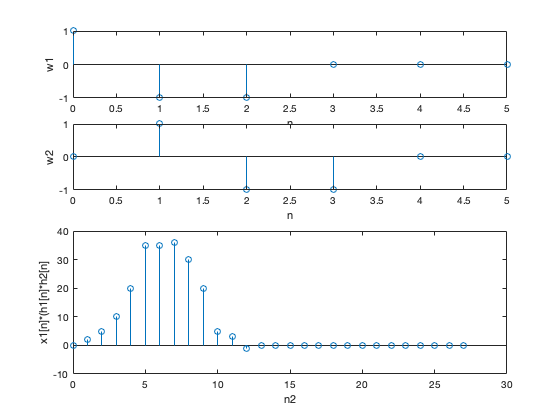

% L2_5a.m

n=[0:5];
w1=((n)==0)-((n-1)==0)-((n-2)==0);  % x[n] =delta[n] ==> x[n]-x[n-1]-x[n-2] = delta[n] -delta[n-1]-delta[n-2]

w2=((n-1)==0)-((n-2)==0)-((n-3)==0);    % x[n] =delta[n-1] ==> x[n]-x[n-1]-x[n-2] = delta[n-1]-delta[n-2]-delta[n-3]
w3= ((n)==0)+((n-1)==0)-3*((n-2)==0)-2*((n-3)==0);
%x[n] =delta[n] +2delta[n-1]
% x[n]-x[n-1]-x[n-2]= delta[n]+2delta[n-1] -(delta[n-1]+2delta[n-2])-(delta[n-2]+2delta[n-3]) = delta[n]+delta[n-1]-3delta[n-2]-2delta[n-3] 
w4=w1+2*w2;
figure(1);
subplot(4,1,1);stem(n,w1);xlabel('n');ylabel('w1');
subplot(4,1,2);stem(n,w2);xlabel('n');ylabel('w2');

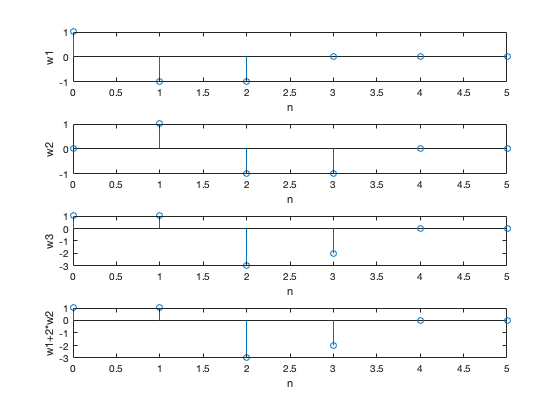

subplot(4,1,3);stem(n,w3);xlabel('n');ylabel('w3');
subplot(4,1,4);stem(n,w4);xlabel('n');ylabel('w1+2*w2');

**2.5 (b)  **Weither or not the above systems is linear?  Justify your answer

**Results Analysis:**

**System 1 is linear. **

**Proof:**

**Let's system 1 is not linear **$\Longrightarrow  w_2[n] \neq w_3[n]$ :

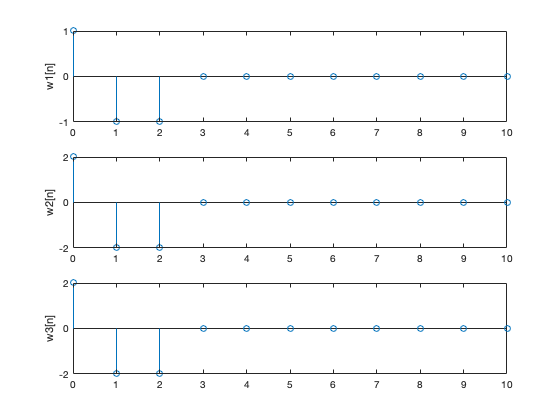

clf;
n=[0:10];
w1=((n)==0)-((n-1)==0)-((n-2)==0);  % x[n] =delta[n] ==> x[n]-x[n-1]-x[n-2] = delta[n] -delta[n-1]-delta[n-2]
w2=2*(((n)==0)-((n-1)==0)-((n-2)==0));     
w3=w1*2;
figure(1);
subplot(3,1,1); stem(n,w1); ylabel('w1[n]');
subplot(3,1,2); stem(n,w2); ylabel('w2[n]');
subplot(3,1,3); stem(n,w3); ylabel('w3[n]');

We can see that $w_2[n] = w_3[n] $ for that reason System is linear.

**Proof:**

**If system 2 is  linear **$\Longrightarrow w_2[n] = w_3[n]$ :

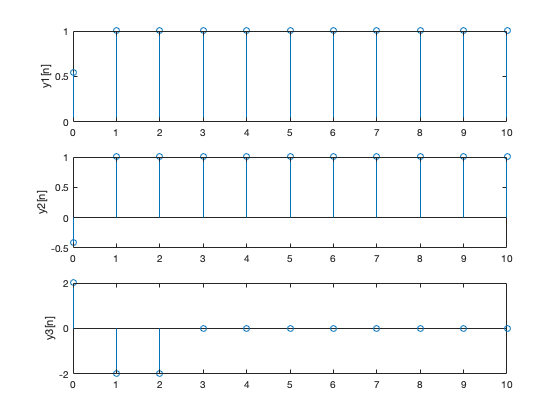

clf;
n=[0:10];
x1=n*0;
x1(1)=1;
x2=2*x1;
y1=cos(x1);
y2=cos(x2);     
y3=w1*2;
figure(2);
subplot(3,1,1); stem(n,y1); ylabel('y1[n]');
subplot(3,1,2); stem(n,y2); ylabel('y2[n]');
subplot(3,1,3); stem(n,y3); ylabel('y3[n]');

We can see that $w_2[n] \neq w_3[n] $ for that reason System is not linear.

**Proof:**

**If system 3 is not  linear **$\Longrightarrow z_2[n] \neq z_3[n]$ :

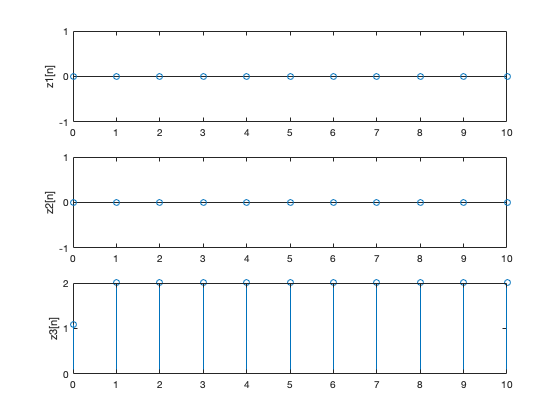

clf;
n=[0:10];
x1=n*0;
x1(1)=1;

x2=2*x1;

z1=n.*x1; %nx[n] x=delta[n] 
z2=n.*x2;     
z3=2*y1;
figure(2);
subplot(3,1,1); stem(n,z1); ylabel('z1[n]');
subplot(3,1,2); stem(n,z2); ylabel('z2[n]');
subplot(3,1,3); stem(n,z3); ylabel('z3[n]');

We can see that $z_2[n] = z_3[n] $ for that reason System is linear.

**2.5 (c)  **Weither or not the above systems is time-invariant?  Justify your answer.

**Results Analysis:**

**Proof:**

**Given the System 1 **

A system is time-invariant if its output signal does not depend on the absolute time. 

$w[n]=x[n]-x[n-1]-x[n-2]$, let $x[n]= \delta[n]$ . 

If $w[n]$ is a time-invariant system then it must follow:

For a input$x_1[n]= \delta[n]$  and let call output  $w_1[n]$ , let , a delayed by 1, $ x_2[n]= \delta[n-1]$  and the output is $w_2[n]$. If the system time-invariant $w_1[n]=w_2[n]$

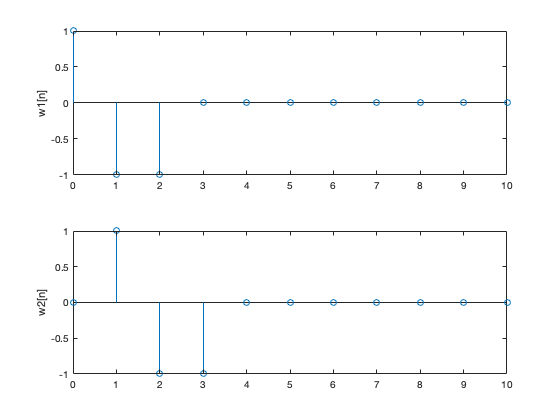

clf;
n=[0:10];
w1=((n)==0)-((n-1)==0)-((n-2)==0);  
w2=((n-1)==0)-((n-2)==0)-((n-3)==0);     
figure(2);
subplot(2,1,1); stem(n,w1); ylabel('w1[n]');
subplot(2,1,2); stem(n,w2); ylabel('w2[n]');

We can see from graph that output signals are not the same $w_1[n] \ne w_2[n]$ for that reason it is not time-invariant.

**Proof:**

**Given the System 2 **

A system is time-invariant if its output signal does not depend on the absolute time. 

$y[n]=cos(x[n])$, let $x[n]= \delta[n]$ . 

If $y[n]$ is a time-invariant system then it must follow:

For a input$x_1[n]= \delta[n]$  and let call output  $y_1[n]$ , let , a delayed by 1, $ x_2[n]= \delta[n-1]$  and the output is $y_2[n]$. If the system time-invariant $y_1[n]=y_2[n]$

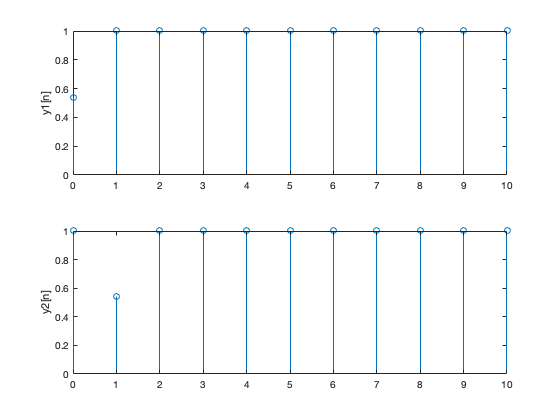

clf;
n=[0:10];
x1=n*0;
x1(1)=1;
x2=n*0;
x2(2)=1;
y1=cos(x1);
y2=cos(x2);     
figure(2);
subplot(2,1,1); stem(n,y1); ylabel('y1[n]');
subplot(2,1,2); stem(n,y2); ylabel('y2[n]');

We can see from graph that output signals are not the same $y_1[n] \ne y_2[n]$ for that reason it is not time-invariant.

**Proof:**

**Given the System 3 **

A system is time-invariant if its output signal does not depend on the absolute time. 

$z[n]=nx[n]$, let $x[n]= \delta[n]$ . 

If $z[n]$ is a time-invariant system then it must follow:

For a input $x_1[n]= \delta[n]$  and let call output  $z_1[n]$ , let , a delayed by 1, $ z_2[n]= \delta[n-1]$  and the output is $z_2[n]$. If the system time-invariant $z_1[n]=z_2[n]$

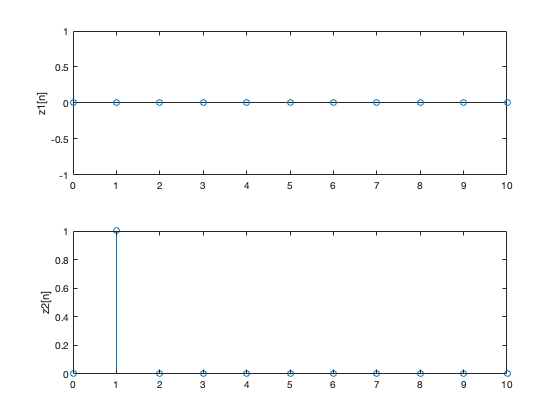

clf;
n=[0:10];
x1=n*0;
x1(1)=1;
x2=n*0;
x2(2)=1;
z1=n.*x1; %nx[n] x=delta[n] 
z2=n.*x2;     
figure(3);
subplot(2,1,1); stem(n,z1); ylabel('z1[n]');
subplot(2,1,2); stem(n,z2); ylabel('z2[n]');

We can see from graph that output signals are not the same $z_1[n] \ne z_2[n]$ for that reason it is not time-invariant.